# Calibrados Renate

## Preparación de la tabla de trabajo

% Crear la variable de trabajo a partir de los datos en bruto
A = rawdata(:, ["Type", "PCDate", "PCTime", "GPSDate", "gpsTime", "stdVal", "CO2Umm", "latitude", "longitude", "equTemp", "licorTemp", "licorPress", "atmPress", "equPress", "H2OFlow", "licorFlow", "IntakeTemp", "TEMP", "SAL", "Oxygen", "Saturation", "Temp",]);

% Añadir la variable de fecha y quitar las variables de GPSDate y gpsTime
A.GPSDate.Format = "dd/MM/uuuu HH:mm:ss";
A.gpsTime.Format = "dd/MM/uuuu HH:mm:ss";

A.PCDate.Format = "dd/MM/uuuu HH:mm:ss";
A.PCTime.Format = "dd/MM/uuuu HH:mm:ss";

for k=1:numel(A.GPSDate)
    if isnat(A.GPSDate(k))
        A.Date(k) = A.PCDate(k) + timeofday(A.PCTime(k));
    else
        A.Date(k) = A.GPSDate(k) + timeofday(A.gpsTime(k));
    end 
end

A.JulianDate = exceltime(A.Date);
A.GPSDate = [];
A.gpsTime = [];

A.PCDate = [];
A.PCTime = [];

% Hallar filas que dieron NaN y eliminarlas
noTime = find(isnan(A.JulianDate));
noTimelist = A(noTime, "Type");
A(noTime, :) = [];
disp(numel(noTime) + " measures had no time so they have been deleted.")

3 measures had no time so they have been deleted.



% Añadir las variables de presión en atm y quitar las variables en bares
A.licorPress2 = A.licorPress * 0.000986923;
A.atmPress2 = A.atmPress * 0.000986923;
A.equPress2 = A.equPress * 0.000986923;

% A.licorPress = [];
% A.atmPress = [];
% A.equPress = [];

% Comprobar los valores de TEMP y SAL que son NaN y hacer NaN los valores de TEMP y SAL que son 0
disp(numel(A.TEMP(A.TEMP == 0)) + " TSG temperature values in " + numel(A.TEMP) + " values are 0.");

404 TSG temperature values in 9414 values are 0.


disp(numel(A.SAL(A.SAL == 0)) + " salinity temperature values in " + numel(A.SAL) + " values are 0.");

407 salinity temperature values in 9414 values are 0.



A.TEMP = standardizeMissing(A.TEMP, 0);
A.SAL = standardizeMissing(A.SAL, 0);

disp(numel(find(isnan(A.TEMP))) + " TSG temperature values are now NaN.");

407 TSG temperature values are now NaN.


disp(numel(find(isnan(A.SAL))) + " salinity values are now NaN.");

410 salinity values are now NaN.



% Encontrar valores nulos de temperatura
nullInt = find(isnan(A.IntakeTemp));
nullTSG = find(isnan(A.TEMP));
nullEqu = find(isnan(A.equTemp));

disp(numel(nullInt) + " Intake temperature values are NaN.");

24 Intake temperature values are NaN.


disp(numel(nullTSG) + " TSG temperature values are NaN.");

407 TSG temperature values are NaN.


disp(numel(nullEqu) + " Equ temperature values are NaN.");

0 Equ temperature values are NaN.



% Encontrar valores erróneos de temperatura
badInt = find(A.IntakeTemp > 30 | A.IntakeTemp < 14);
badTSG = find(A.TEMP > 35 | A.TEMP < 14);
badEqu = find(A.equTemp > 35 | A.equTemp < 14);

disp("There are " + numel(badInt) + " wrong Intake Temperature values in " + numel(A.IntakeTemp) + " values.");

There are 39 wrong Intake Temperature values in 9414 values.


disp("There are " + numel(badTSG) + " wrong TSG Temperature values in " + numel(A.TEMP) + " values.");

There are 7 wrong TSG Temperature values in 9414 values.


disp("There are " + numel(badEqu) + " wrong Equ Temperature values in " + numel(A.equTemp) + " values.");

There are 0 wrong Equ Temperature values in 9414 values.



% Convertir en NaN los valores erróneos de temperatura
A.IntakeTemp = standardizeMissing(A.IntakeTemp, A.IntakeTemp(badInt));
A.TEMP = standardizeMissing(A.TEMP, A.TEMP(badTSG));
A.equTemp = standardizeMissing(A.equTemp, A.equTemp(badEqu));

disp(numel(find(isnan(A.IntakeTemp))) + " Intake temperature values are now NaN.");

63 Intake temperature values are now NaN.


disp(numel(find(isnan(A.TEMP))) + " TSG temperature values are now NaN.");

414 TSG temperature values are now NaN.


disp(numel(find(isnan(A.equTemp))) + " Equ temperature values are now NaN.");

0 Equ temperature values are now NaN.



% Añadir las variables de diferencia de temperatura 
A.DiffEquInt = A.equTemp - A.IntakeTemp;
A.DiffTSGint = A.TEMP - A.IntakeTemp;
A.DiffEquTSG = A.equTemp - A.TEMP;

% Hallar diferencias de temperatura mayores de 2 grados y menores de cero,
% así como valores NaN
badDiffEquInt= find(abs(A.DiffEquInt) > 2 | A.DiffEquInt < 0);
badDiffEquInt2 = find(abs(A.DiffEquInt) > 1.5 | A.DiffEquInt < 0);
nullDiffEquInt = find(isnan(A.DiffEquInt));

disp(numel(nullDiffEquInt) + " difference values are NaN.");

63 difference values are NaN.


disp("There are " + numel(badDiffEquInt) + " bad difference values (some of them are > 2) in " + numel(A.DiffEquInt) + " values.");

There are 28 bad difference values (some of them are > 2) in 9414 values.


disp("There are " + numel(badDiffEquInt2) + " bad difference values (some of them are > 1.5) in " + numel(A.DiffEquInt) + " values.");

There are 28 bad difference values (some of them are > 1.5) in 9414 values.



% Convertir en NaN estos valores de diferencia de temperatura
A.DiffEquInt = standardizeMissing(A.DiffEquInt, A.DiffEquInt([badDiffEquInt; badDiffEquInt2]));
allNullDiffEquInt = find(isnan(A.DiffEquInt));
CO2nullDiffEquInt = find(A.Type == "EQU" & isnan(A.DiffEquInt));
disp(numel(find(allNullDiffEquInt)) + " Equ-Int difference values are now NaN.");

91 Equ-Int difference values are now NaN.


disp(numel(CO2nullDiffEquInt) + " Equ-Int difference values for Equ CO2 are NaN.");

50 Equ-Int difference values for Equ CO2 are NaN.



% Encontrar valores erróneos de salinidad y convertirlos en NaN. Hallar
% también valores NaN inicialmente
badSAL = find(A.SAL < 34);
nullSAL = find(isnan(A.SAL));
disp(numel(nullSAL) + " Salinity values are NaN.");

410 Salinity values are NaN.


disp("There are " + numel(badSAL) + " wrong salinity values in " + numel(A.SAL) + " values.");

There are 3 wrong salinity values in 9414 values.


A.SAL = standardizeMissing(A.SAL, A.SAL(badSAL));
disp(numel(find(isnan(A.SAL))) + " salinity values are now NaN.");

413 salinity values are now NaN.



% Encontrar valores erróneos de presión atmosférica y convertirlos en NaN.
% Hallar también valores NaN iniciales
badPress = find(A.atmPress2 < 0.9);
nullPress = find(isnan(A.atmPress2));
disp(numel(nullPress) + " atm pressure values are NaN.");

0 atm pressure values are NaN.


disp("There are " + numel(badPress) + " wrong pressure values in " + numel(A.atmPress2) + " values.");

There are 8 wrong pressure values in 9414 values.


A.atmPress2 = standardizeMissing(A.atmPress2, A.atmPress2(badPress));
disp(numel(find(isnan(A.atmPress2))) + " pressure values are now NaN.");

8 pressure values are now NaN.



% Encontrar valores erróneos de flujo de agua en el equilibrador y convertirlos en NaN.
% Hallar también valores NaN iniciales
badH2O = find(A.H2OFlow < 2.5);
nullH2O = find(isnan(A.H2OFlow));
disp(numel(nullH2O) + " H2O flow values are NaN.");

0 H2O flow values are NaN.


disp("There are " + numel(badH2O) + " wrong H2O flow values in " + numel(A.H2OFlow) + " values.");

There are 27 wrong H2O flow values in 9414 values.


%A.H2OFlow = standardizeMissing(A.H2OFlow, A.H2OFlow(badH2O));
allNullH2O = find(isnan(A.H2OFlow));
disp(numel(allNullH2O) + " H2O flow values are now NaN.");

0 H2O flow values are now NaN.


CO2nullH2O = find(A.Type == "EQU" & isnan(A.H2OFlow));
disp(numel(CO2nullH2O) + " H2O flow values for Equ CO2 are NaN.");

0 H2O flow values for Equ CO2 are NaN.



% Encontrar valores erróneos de CO2 y convertirlos en NaN. Eliminar también
% valores para los que la temperatura y el flujo de agua son erróneos
badCO2 = find(A.Type == "EQU" & (A.CO2Umm > 500 | A.CO2Umm < 360));
disp("There are " + numel(badCO2) + " bad CO2 values in " + numel(A.CO2Umm) + " values.");

There are 0 bad CO2 values in 9414 values.


disp("There are " + numel(find(isnan(A.CO2Umm))) + " NaN CO2 values in " + numel(A.CO2Umm) + " values.");

There are 0 NaN CO2 values in 9414 values.



%A.CO2Umm(sort([CO2nullDiffEquInt;CO2nullH2O;badCO2])) = NaN; 
disp(numel(find(isnan(A.CO2Umm))) + " CO2 values in " + numel(A.CO2Umm) + " are now NaN.");

0 CO2 values in 9414 are now NaN.


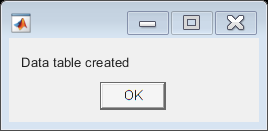


% Recolocar las columnas en la tabla
A = movevars(A, ["DiffEquInt" "DiffTSGint", "DiffEquTSG"], "After", "Temp");
A = movevars(A, ["Date", "JulianDate"], "After", "Type");

% Ordenar las filas por fecha
A = sortrows(A, "Date");

msgbox("Data table created");

## Representar las distintas variables

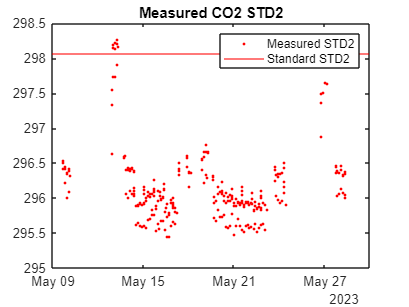

% Representar los valores medidos de los gases con su valor estándar
plot(A.Date(A.Type == "STD2"), A.CO2Umm(A.Type == "STD2"), ".r") % Gas 2
hold on
yline(298.06, 'r')
hold off
title("Measured CO2 STD2")
legend("Measured STD2", "Standard STD2", "Location", "northeast")

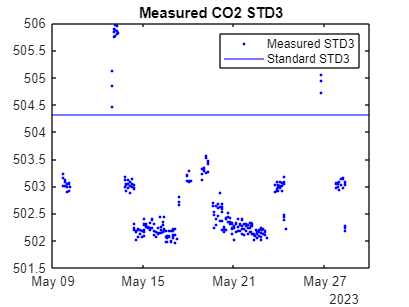


plot(A.Date(A.Type == "STD3"), A.CO2Umm(A.Type == "STD3"), ".b") % Gas 3
hold on
yline(504.32, 'b')
hold off
title("Measured CO2 STD3")
legend("Measured STD3", "Standard STD3", "Location", "northeast")

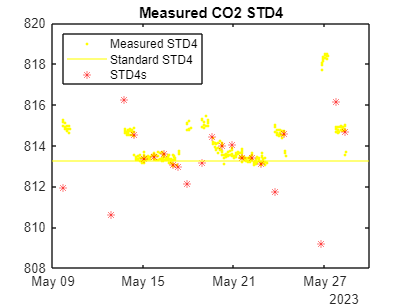


plot(A.Date(A.Type == "STD4"), A.CO2Umm(A.Type == "STD4"), ".y") % Gas 4
hold on
yline(813.27, 'y')
hold on
plot(A.Date(A.Type == "STD4s"), A.CO2Umm(A.Type == "STD4s"), "*r")
hold off
title("Measured CO2 STD4")
legend("Measured STD4", "Standard STD4", "STD4s", "Location", "northwest")

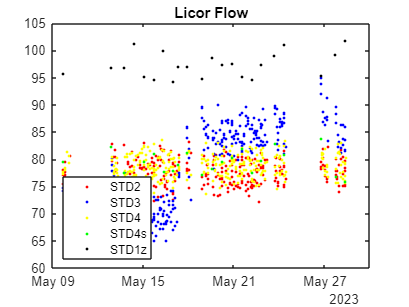



% Representar licor flow de los gases y de las mediciones atmosféricas y
% equilibrador
plot(A.Date(A.Type == "STD2"), A.licorFlow(A.Type == "STD2"), ".r") 
hold on
plot(A.Date(A.Type == "STD3"), A.licorFlow(A.Type == "STD3"), ".b")
hold on
plot(A.Date(A.Type == "STD4"), A.licorFlow(A.Type == "STD4"), ".y")
hold on
plot(A.Date(A.Type == "STD4s"), A.licorFlow(A.Type == "STD4s"), ".g")
hold on
plot(A.Date(A.Type == "STD1z"), A.licorFlow(A.Type == "STD1z"), ".k")
hold off
title("Licor Flow")
legend("STD2", "STD3", "STD4", "STD4s", "STD1z", "Location", "southwest")

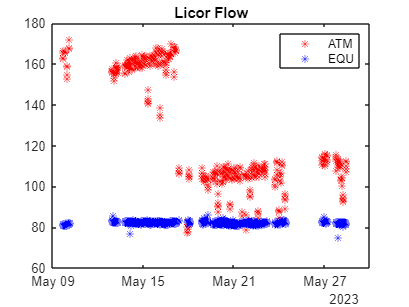


plot(A.Date(A.Type == "ATM"), A.licorFlow(A.Type == "ATM"), "*r")
hold on
plot(A.Date(A.Type == "EQU"), A.licorFlow(A.Type == "EQU"), "*b")
hold off
title("Licor Flow")
legend("ATM", "EQU")

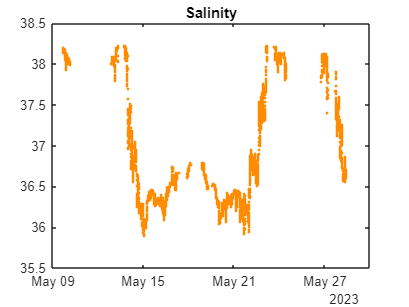

    

% Salinidad
plot(A.Date, A.SAL, ".", "Color", "#FF8C00")
title("Salinity")

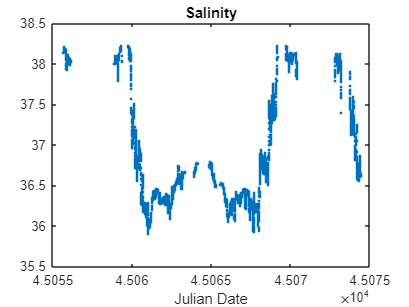

%ylim([35 39])

plot(A.JulianDate, A.SAL, ".")
title("Salinity")
xlabel("Julian Date")

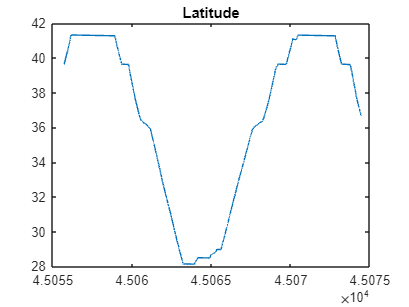

%ylim([35 39])


% Coordenadas
plot(A.JulianDate, A.latitude)
title("Latitude")

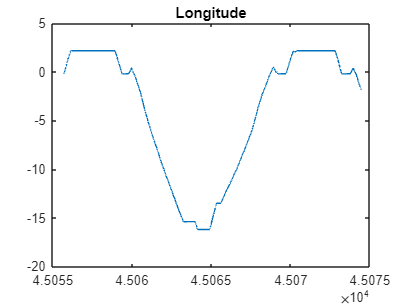


plot(A.JulianDate, A.longitude)
title("Longitude")

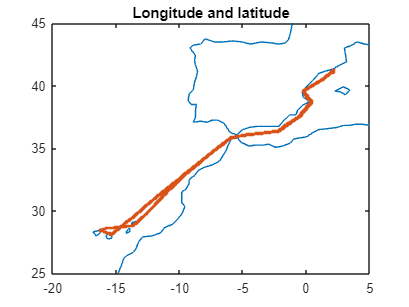


% Obtener las coordenadas máximas y mínimas medidas para comprobar si hay algún error
coord = table(min(A.longitude), min(A.latitude), max(A.longitude), max(A.latitude), 'VariableNames', {'minLon', 'minLat', 'maxLon', 'maxLat'});

load coastlines
plot(coastlon, coastlat)
hold on 
plot(A.longitude, A.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

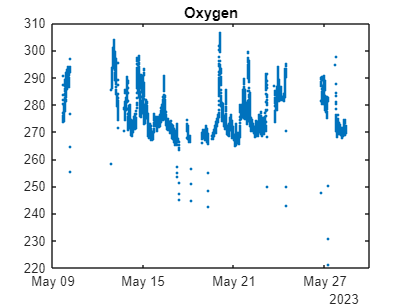



% Oxígeno
plot(A.Date, A.Oxygen, ".")
title("Oxygen")

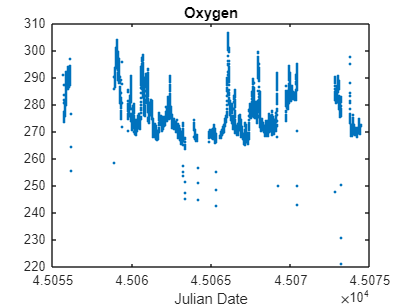

%ylim([200 350])

plot(A.JulianDate, A.Oxygen, ".")
title("Oxygen")
xlabel("Julian Date")

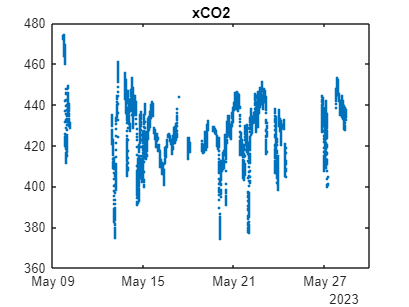

%ylim([200 350])


% xCO2 en el equilibrador
plot(A.Date(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("xCO2")

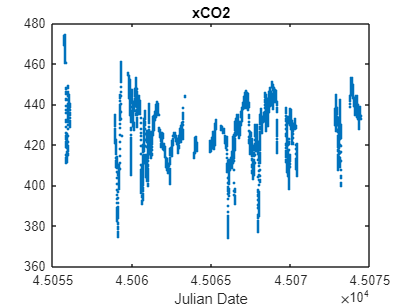

% ylim([350 550])

plot(A.JulianDate(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("xCO2")
xlabel("Julian Date")

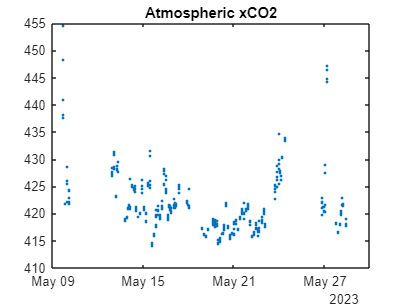

% ylim([350 550])


% xCO2 atmosférico
plot(A.Date(A.Type == "ATM"), A.CO2Umm(A.Type == "ATM"), ".")
title("Atmospheric xCO2")

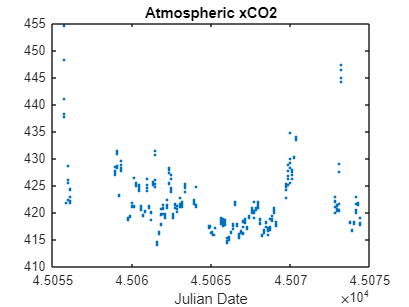

% ylim([350 550])

plot(A.JulianDate(A.Type == "ATM"), A.CO2Umm(A.Type == "ATM"), ".")
title("Atmospheric xCO2")
xlabel("Julian Date")

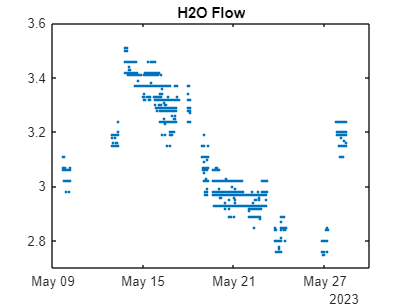

% ylim([350 550])


% Flujo de agua en el equilibrador
plot(A.Date(A.Type == "EQU"), A.H2OFlow(A.Type == "EQU"), ".")
% ylim([-0.5, 3.5])
title("H2O Flow")

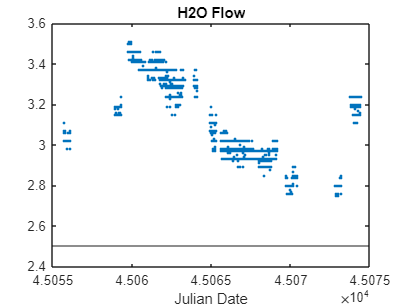

%ylim([0, 3.8])

plot(A.JulianDate(A.Type == "EQU"), A.H2OFlow(A.Type == "EQU"), ".")
hold on
yline(2.5)
hold off
% ylim([-0.5, 3.5])
title("H2O Flow")
xlabel("Julian Date")

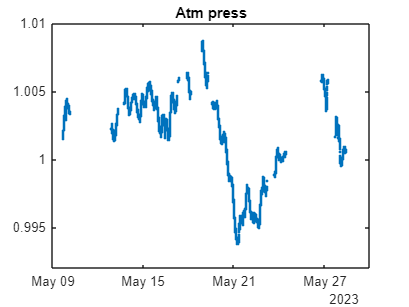



% Presiones

% Atm press
plot(A.Date, A.atmPress2, ".")
title("Atm press")

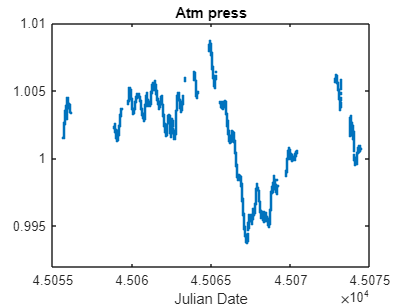

%ylim([0.97 1.03])

plot(A.JulianDate, A.atmPress2, ".")
title("Atm press")
xlabel("Julian Date")

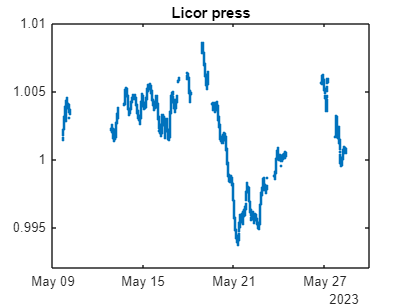

%ylim([0.97 1.03])

% Licor Press
plot(A.Date, A.licorPress2, ".")
title("Licor press")

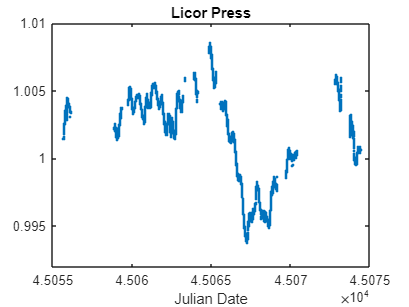


plot(A.JulianDate, A.licorPress2, ".")
title("Licor Press")
xlabel("Julian Date")

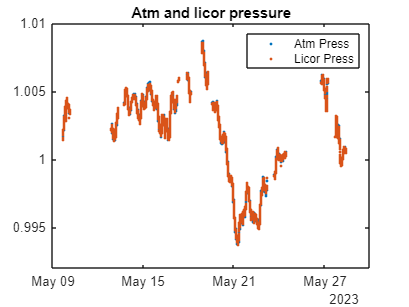


% Juntas
plot(A.Date, A.atmPress2, ".")
hold on
plot(A.Date, A.licorPress2, ".")
hold off
title("Atm and licor pressure")
legend("Atm Press", "Licor Press")

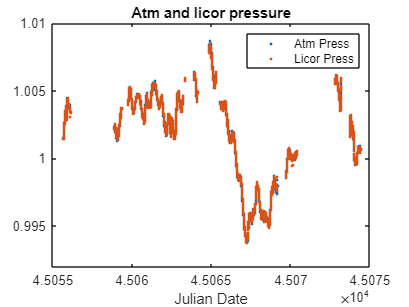

%ylim([0.97 1.03])

plot(A.JulianDate, A.atmPress2, ".")
hold on
plot(A.JulianDate, A.licorPress2, ".")
hold off
title("Atm and licor pressure")
legend("Atm Press", "Licor Press")
xlabel("Julian Date")

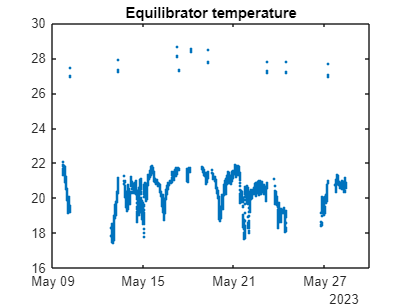

%ylim([0.97 1.03])


% Temperaturas

% Equ Temp
plot(A.Date, A.equTemp, ".")
title("Equilibrator temperature")

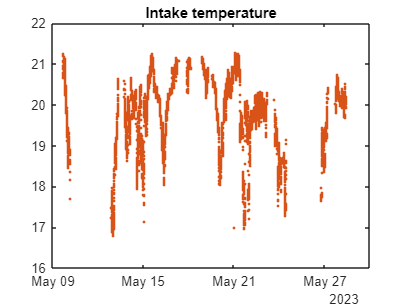

%ylim([14 32])

% Intake temp
plot(A.Date, A.IntakeTemp, ".", "Color", "#D95319")
title("Intake temperature")

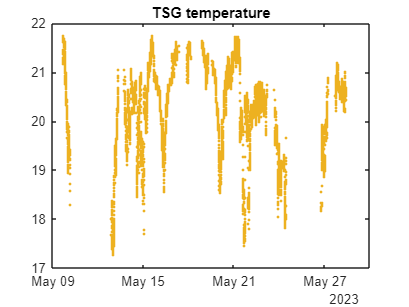

%ylim([11 24])
% A veces da valores de miles que habría que quitar

% TSG temp
plot(A.Date, A.TEMP, ".", "Color", 	"#EDB120")
title("TSG temperature")

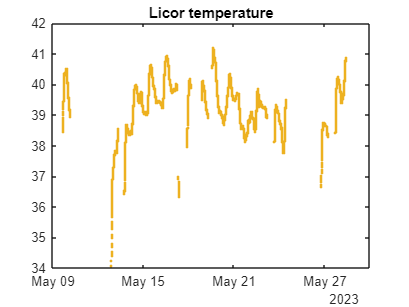

%ylim([14 30])
% A veces da valores de miles que habría que quitar 

% Licor temp
plot(A.Date, A.licorTemp, ".", "Color", "#EDB120")
title("Licor temperature")

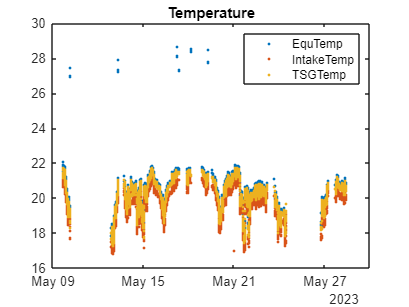

% ylim([14 30])

% Todas juntas menos licor temp
plot(A.Date, A.equTemp, ".")
hold on
plot(A.Date, A.IntakeTemp, ".")
hold on
plot(A.Date, A.TEMP, ".")
hold off
title("Temperature")
legend("EquTemp", "IntakeTemp", "TSGTemp")

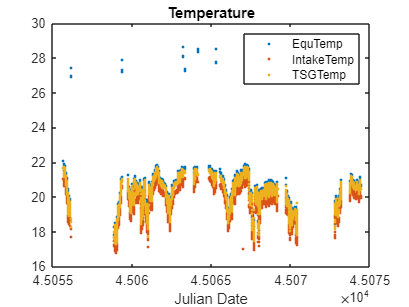

% ylim([15 24])
%ylim([12 32])

plot(A.JulianDate, A.equTemp, ".")
hold on
plot(A.JulianDate, A.IntakeTemp, ".")
hold on
plot(A.JulianDate, A.TEMP, ".")
hold off
title("Temperature")
legend("EquTemp", "IntakeTemp", "TSGTemp")
% ylim([15 30])
xlabel("Julian Date")

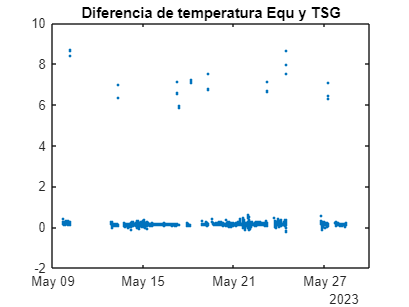

%ylim([12 32])


% Diferencias de temperatura

% Equ y TSG
plot(A.Date, A.DiffEquTSG, ".")
title("Diferencia de temperatura Equ y TSG")

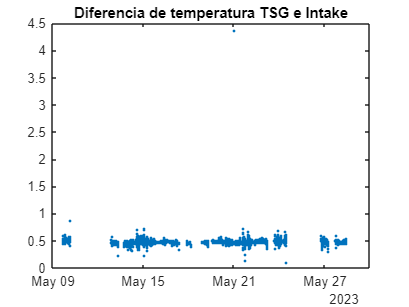

%ylim([-0.5 2.5])

% TSG e Intake
plot(A.Date, A.DiffTSGint, ".")
title("Diferencia de temperatura TSG e Intake")

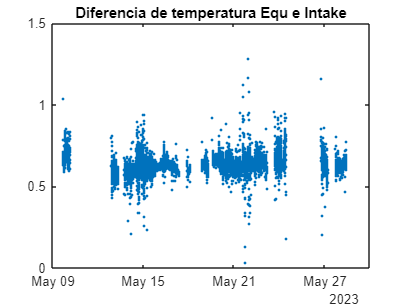

%ylim([0 2])

% Equ e Intake
plot(A.Date, A.DiffEquInt, ".")
title("Diferencia de temperatura Equ e Intake")
%ylim([0 2])
hold on
yline(1.5)
hold off

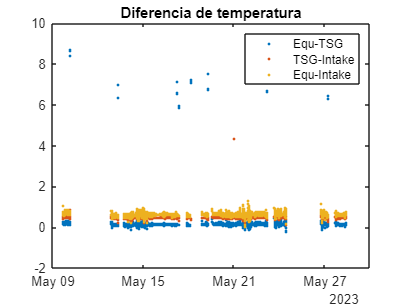


% Juntas 
plot(A.Date, A.DiffEquTSG, ".")
hold on
plot(A.Date, A.DiffTSGint, ".")
hold on
plot(A.Date, A.DiffEquInt, ".")
hold off
title("Diferencia de temperatura")
legend("Equ-TSG", "TSG-Intake", "Equ-Intake")

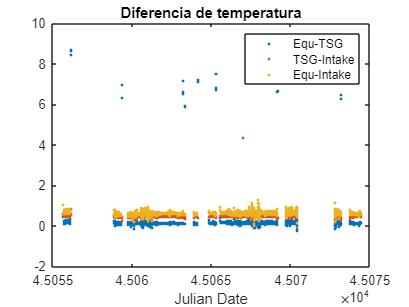

%ylim([-0.5 2])

plot(A.JulianDate, A.DiffEquTSG, ".")
hold on
plot(A.JulianDate, A.DiffTSGint, ".")
hold on
plot(A.JulianDate, A.DiffEquInt, ".")
hold off
title("Diferencia de temperatura")
legend("Equ-TSG", "TSG-Intake", "Equ-Intake")
xlabel("Julian Date")

%ylim([-0.5 2])

## Preparación de tabla con los índices de los estándares

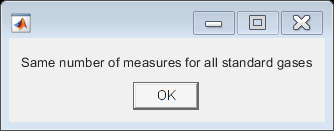

% Hallar los índices de cada tipo
STD2Rows = find(A.Type == "STD2");
STD3Rows = find(A.Type == "STD3");
STD4Rows = find(A.Type == "STD4");
STD4sRows = find(A.Type == "STD4s");
STD1Rows = find(A.Type == "STD1z");
EQUrows = find(A.Type == "EQU");
STDsRows = find(A.Type == "STD2" | A.Type == "STD3" | A.Type == "STD4" | A.Type == "STD4s" | A.Type == "STD1z");

% Indicar si los estándares presentan el mismo número de medidas (filas)
if any([size(STD2Rows) ~= size(STD3Rows), size(STD2Rows) ~= size(STD4Rows), size(STD3Rows) ~= size(STD4Rows)])
   msgbox("Some standard gases have not the same number of measures");
else 
   msgbox("Same number of measures for all standard gases");
end

% Buscar los grupos y medidas sueltas de cada uno de los estándares con
% una función creada para ello (ver final del script)

disp("STD2");

STD2


[groups2, singles2, singles2A] = loopSTDs(STD2Rows); % STD2

98 groups and 9 singles in: 
          13         400
          26         804
         123        3922
         127        3943
         134        4143
         147        4535
         247        7762
         269        8427
         282        8799



disp("STD3");

STD3


[groups3, singles3, singles3A] = loopSTDs(STD3Rows); % STD3

98 groups and 9 singles in: 
          13         401
          26         805
         123        3923
         127        3944
         134        4144
         147        4536
         247        7763
         269        8428
         282        8800



disp("STD4");

STD4


[groups4, singles4, singles4A] = loopSTDs(STD4Rows); % STD4

98 groups and 9 singles in: 
          13         402
          26         806
         123        3924
         127        3945
         134        4145
         147        4537
         247        7764
         269        8429
         282        8801



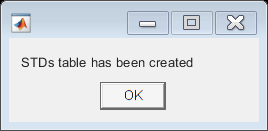


% Preguntar si quieres eliminar los singles 
askDelete = "Remove singles? y/n: ";
ansDelete = input(askDelete, "s");

if ansDelete == "y"
   STD2Rows(singles2, :) = [];
   STD3Rows(singles3, :) = [];
   STD4Rows(singles4, :) = [];
end

clc

% Crear tabla si todos los gases tienen el mismo número de medidas
if numel(STD2Rows) == numel(STD3Rows) && numel(STD3Rows) == numel(STD4Rows)
    STDs = [STD2Rows, STD3Rows, STD4Rows]; % Crear tabla con los índices de los estándares
    msgbox("STDs table has been created");
else
    msgbox("One or more gases have different number of grouped measures");
end

% Crear tabla si todos los gases tienen el mismo número de medidas después
% de corregir a mano
if numel(STD2Rows) == numel(STD3Rows) && numel(STD3Rows) == numel(STD4Rows)
    STDs = [STD2Rows, STD3Rows, STD4Rows]; % Crear tabla con los índices de los estándares
    msgbox("STDs table has been created");
else
    msgbox("One or more gases have different number of grouped measures");
end

## Calcular la media de CO2 para las tres medidas de los estándares

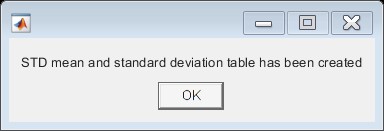

% Crear variables vacías iniciales
%means = zeros(numel(STDs(:,1)), 1);
%dates = datetime((zeros(numel(STDs(:,1)), 1)), 'ConvertFrom', 'datenum');
means = [];
dates = [];
dev = [];
type = [];

% Recorrer la lista de índices de los estándares de arriba a abajo
for i = 1:numel(STDs(:,1))

    % Para los últimos tres valores de la lista de índices
    if (i == numel(STDs(:,1))-3) && (diff(STDs((i+1):(i+2),1)) == 1)

        % Cálculo de la Media
        STD2mean = mean([A.CO2Umm(STDs(i+1, 1)), A.CO2Umm(STDs(i+2, 1)), A.CO2Umm(STDs(i+3, 1))]);
        STD3mean = mean([A.CO2Umm(STDs(i+1, 2)), A.CO2Umm(STDs(i+2, 2)), A.CO2Umm(STDs(i+3, 2))]);
        STD4mean = mean([A.CO2Umm(STDs(i+1, 3)), A.CO2Umm(STDs(i+2, 3)), A.CO2Umm(STDs(i+3, 3))]);
        
        % Cálculo de la Desviación estándar
        STD2dev = std([A.CO2Umm(STDs(i+1, 1)), A.CO2Umm(STDs(i+2, 1)), A.CO2Umm(STDs(i+3, 1))]);
        STD3dev = std([A.CO2Umm(STDs(i+1, 2)), A.CO2Umm(STDs(i+2, 2)), A.CO2Umm(STDs(i+3, 2))]);
        STD4dev = std([A.CO2Umm(STDs(i+1, 3)), A.CO2Umm(STDs(i+2, 3)), A.CO2Umm(STDs(i+3, 3))]); 
        
        % Creación de las futuras columnas Type, Mean, StdDev, Date
        type = [type; "STD2"; "STD3"; "STD4"];
        dates = [dates; A.Date(STDs(i+2,1)); A.Date(STDs(i+2,2)); A.Date(STDs(i+2,3))];
        means = [means; STD2mean; STD3mean; STD4mean];
        dev = [dev; STD2dev; STD3dev; STD4dev];
        
    % Para el resto de valores en grupos de tres
    elseif i < numel(STDs(:,1))-3 && (diff(STDs(i:(i+1),1)) == 1) && (diff(STDs(i+2:(i+3),1)) ~= 1)

        % Cálculo de la Media
        STD2mean = mean([A.CO2Umm(STDs(i, 1)), A.CO2Umm(STDs(i+1, 1)), A.CO2Umm(STDs(i+2, 1))]);
        STD3mean = mean([A.CO2Umm(STDs(i, 2)), A.CO2Umm(STDs(i+1, 2)), A.CO2Umm(STDs(i+2, 2))]);
        STD4mean = mean([A.CO2Umm(STDs(i, 3)), A.CO2Umm(STDs(i+1, 3)), A.CO2Umm(STDs(i+2, 3))]);

        % Cálculo de la Desviación estándar
        STD2dev = std([A.CO2Umm(STDs(i, 1)), A.CO2Umm(STDs(i+1, 1)), A.CO2Umm(STDs(i+2, 1))]);
        STD3dev = std([A.CO2Umm(STDs(i, 2)), A.CO2Umm(STDs(i+1, 2)), A.CO2Umm(STDs(i+2, 2))]);
        STD4dev = std([A.CO2Umm(STDs(i, 3)), A.CO2Umm(STDs(i+1, 3)), A.CO2Umm(STDs(i+2, 3))]);
        
        % Creación de loas futuras columnas Type, Mean, StdDev, Date
        type = [type; "STD2"; "STD3"; "STD4"];
        dates = [dates; A.Date(STDs(i+1,1)); A.Date(STDs(i+1,2)); A.Date(STDs(i+1,3))];
        means = [means; STD2mean; STD3mean; STD4mean];
        dev = [dev; STD2dev; STD3dev; STD4dev];

    end
end

% Crear tabla con la media de los estándares
STDsMeans = table(type, dates, means, dev, 'VariableNames', {'Type', 'Date', 'Mean', 'StdDev'});
msgbox("STD mean and standard deviation table has been created");

## Tabla para ir comprobando la evolución de los estándares

% Crear tabla con todos los estándares, incluidos los calibrados span y
% zoom 
allType = A.Type(STDsRows);
allCO2 = A.CO2Umm(STDsRows);
allDate = A.Date(STDsRows);


STDsVal = A(STDsRows, :);

% Crear una matriz que combine los valores de todos los estándares con los
% de la media y la desviación estándar calculados anteriormente

k = 1;
C = [];
null = [NaN NaN];

for i = 1:numel(STDsVal(:,1))
    if (STDsVal.Type(i) == STDsMeans.Type(k)) && (STDsVal.Date(i) == STDsMeans.Date(k)) && (k < numel(STDsMeans(:,1)))
        C = [C; STDsMeans.Mean(k), STDsMeans.StdDev(k)];
        k = k + 1;
    
    elseif (STDsVal.Type(i) == STDsMeans.Type(k)) && (STDsVal.Date(i) == STDsMeans.Date(k)) && (k == numel(STDsMeans(:, 1)))
        C = [C; STDsMeans.Mean(k), STDsMeans.StdDev(k)];
        k = k;
    else
        C = [C; null];
    end
end

% Añadir las variables de media y desviación a la tabla que recoge los
% estándares
STDsVal.Mean = C(:,1);
STDsVal.StdDev = C(:, 2);

% Recolocar las columnas en la tabla
STDsVal = movevars(STDsVal, ["Mean" "StdDev"], "After", "Type");
STDsVal = movevars(STDsVal, "Date", "After", "Type");

% Guardar la tabla de medias y desviación estándar
writetable(STDsVal, 'STDsMeanStd.csv', 'Delimiter', '\t');

## Crear tabla para hacer la interpolación

% Crear una matriz del mismo tamaño que la tabla principal que incluya los
% valores de media y desviación calculados en el lugar en el que irían si
% la uniéramos a la tabla principal

m = 1;
D = [];
null = [NaN NaN];

for j = 1:numel(A(:,1))
    if (A.Type(j) == STDsMeans.Type(m)) && (A.Date(j) == STDsMeans.Date(m)) && (m < numel(STDsMeans(:, 1)))
        D = [D; STDsMeans.Mean(m), STDsMeans.StdDev(m)];
        m = m + 1;
    
    elseif (A.Type(j) == STDsMeans.Type(m)) && (A.Date(j) == STDsMeans.Date(m)) && (m == numel(STDsMeans(:, 1)))
        D = [D; STDsMeans.Mean(m), STDsMeans.StdDev(m)];
        m = m;
    else
        D = [D; null];
    end
end

% Crear matriz principal duplicada
A2 = A;

% Añadir la matriz calculada a la tabla principal como variables
A2.Mean = D(:, 1);
A2.StdDev = D(:,2);

% Añadir los valores de estándares individuales a la columna de media
A2.Mean([singles2A; singles3A; singles4A]) = A2.CO2Umm([singles2A; singles3A; singles4A]);

% Crear una nueva tabla
A3 = A2;

% Eliminar las filas que son repeticiones de las medidas de los estándares
A3((A2.Type == "STD2" | A2.Type == "STD3" | A2.Type == "STD4") & isnan(A2.Mean), :) = [];

writetable(A3, 'Ready4interpolTest.csv', 'Delimiter', '\t');

## INTERPOLACIÓN

% Crear columnas para cada estándar
STD2column = A3.Mean(:);
STD3column = A3.Mean(:);
STD4column = A3.Mean(:);

% Hallar los índices que no corresponden a cada estándar
nonSTD2 = find(A3.Type ~= "STD2");
nonSTD3 = find(A3.Type ~= "STD3");
nonSTD4 = find(A3.Type ~= "STD4");

% Hacer NaN en los valores que no corresponden a cada estándar
STD2column(nonSTD2) = NaN;
STD3column(nonSTD3) = NaN;
STD4column(nonSTD4) = NaN;

% Combinar las columnas de cada estándar con la Julian Date
julianDate = A3{:, "JulianDate"};
STDtable = table(STD2column, STD3column, STD4column, julianDate);

% Interpolar los valores NaN y añadirlo a la tabla
interpol = fillmissing(STDtable(:, 1:3), 'linear', 'SamplePoints', STDtable.julianDate);
A3 = [A3, interpol];

% Guardar tabla completa
% writetable(A3, 'interpol2.csv', 'Delimiter', '\t');

## Calcular pendiente e intersección y corregir valores de xCO2

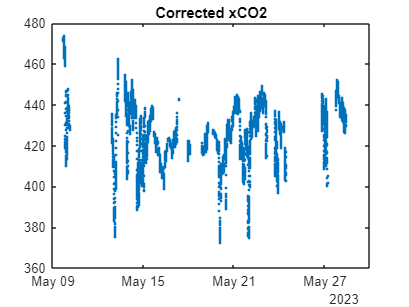

% Calcular valor de la pendiente y de la intersección
standardVals = [298.06, 504.32, 813.27];
STDcolumns = [A3.STD2column, A3.STD3column, A3.STD4column];
line = zeros(numel(A3.STD2column), 2);

for i=1:numel(STDcolumns(:, 1))
    line(i, :) = polyfit(standardVals(:), STDcolumns(i, :), 1);
end

% Corregir valores de CO2

CO2corr = zeros(numel(line(:, 1)), 1);

for i=1:numel(line(:, 1))
    CO2corr(i) = polyval(line(i, :), A3.CO2Umm(i));
end

A3.CO2corr = CO2corr;
A3 = movevars(A3, "CO2corr", "After", "CO2Umm");

% Representar valores corregidos
plot(A3.Date(A3.Type == "EQU"), A3.CO2corr(A3.Type == "EQU"), ".")
title("Corrected xCO2")

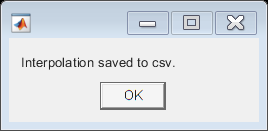

% Eliminar y reorganizar variables 
A3 = removevars(A3, "stdVal");
A3 = removevars(A3, "StdDev");
A3 = movevars(A3, "Date", "After", "JulianDate");
A3 = movevars(A3, "CO2Umm", "After", "Date");
A3 = movevars(A3, "Mean", "After", "CO2Umm");
A3 = movevars(A3, "CO2corr", "After", "STD4column");
A3 = movevars(A3, "licorPress2", "Before", "licorPress");
A3 = movevars(A3, "atmPress2", "Before", "atmPress");
A3 = movevars(A3, "equPress2", "Before", "equPress");

% Guardar tabla de interpolación y corrección en un csv
ask1 = "Interpolation table created. Generate csv file? y/n: ";
answer1 = input(ask1, "s");

if answer1 == "y"
    csvName = strcat("C:\Users\usuario\Desktop\Renate-files\", "interpol", file, ".csv");
    writetable(A3, csvName, 'Delimiter', '\t');
    msgbox("Interpolation saved to csv.");
else
    msgbox("Interpolation not saved to csv.");
end

## Representar la media y la desviación estándar de los estándares con su valor original

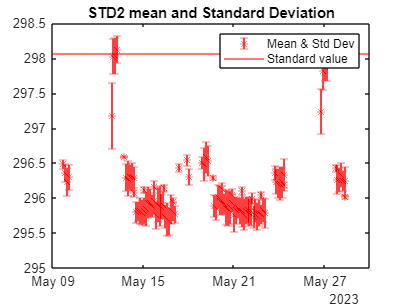

errorbar(STDsMeans.Date(STDsMeans.Type == "STD2"), STDsMeans.Mean(STDsMeans.Type == "STD2"), STDsMeans.StdDev(STDsMeans.Type == "STD2"), "r*")
hold on
yline(298.06, 'r')
hold off
title("STD2 mean and Standard Deviation")
legend("Mean & Std Dev", "Standard value", "Location", "northeast")

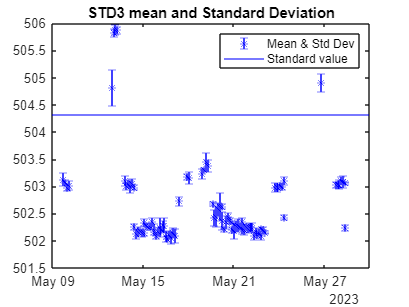


errorbar(STDsMeans.Date(STDsMeans.Type == "STD3"), STDsMeans.Mean(STDsMeans.Type == "STD3"), STDsMeans.StdDev(STDsMeans.Type == "STD3"), "b*")
hold on
yline(504.32, 'b')
hold off
title("STD3 mean and Standard Deviation")
legend("Mean & Std Dev", "Standard value", "Location", "northeast")

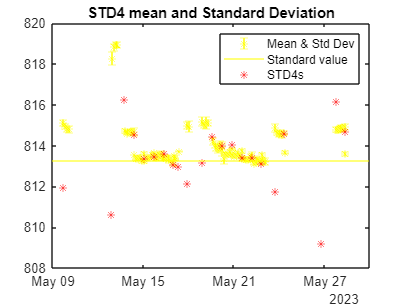


errorbar(STDsMeans.Date(STDsMeans.Type == "STD4"), STDsMeans.Mean(STDsMeans.Type == "STD4"), STDsMeans.StdDev(STDsMeans.Type == "STD4"), "y*")
hold on
yline(813.27, 'y')
hold on
plot(A.Date(A.Type == "STD4s"), A.CO2Umm(A.Type == "STD4s"), "*r")
hold off
title("STD4 mean and Standard Deviation")
legend("Mean & Std Dev", "Standard value", "STD4s")

% ylim([805 825])